# Interpolate Magnetic Flux Density in 2-D Magnetostatic Analysis

Create an electromagnetic model for magnetostatic analysis.

emagmodel = createpde("electromagnetic","magnetostatic");

Create a square geometry and include it in the model. Plot the geometry with the edge labels.

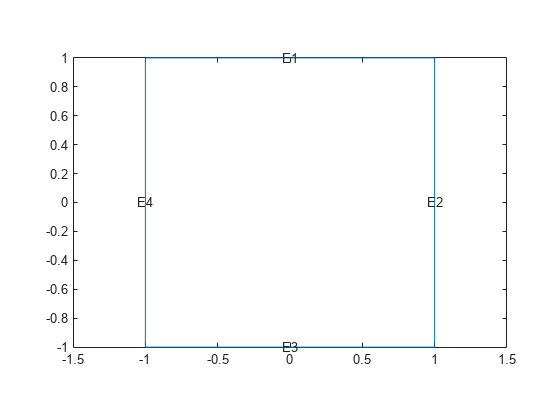

R1 = [3,4,-1,1,1,-1,1,1,-1,-1]';
g = decsg(R1,'R1',('R1')');
geometryFromEdges(emagmodel,g);
pdegplot(emagmodel,"EdgeLabels","on")
xlim([-1.5 1.5])
axis equal

Specify the vacuum permeability in the SI system of units.

emagmodel.VacuumPermeability = 1.2566370614E-6;

Specify the relative permeability of the material.

electromagneticProperties(emagmodel,"RelativePermeability",5000);

Apply the magnetic potential boundary conditions on the boundaries of the square.

electromagneticBC(emagmodel,"MagneticPotential",0,"Edge",[1 3]); 
electromagneticBC(emagmodel,"MagneticPotential",0.01,"Edge",[2 4]);

Specify the current density for the entire geometry.

electromagneticSource(emagmodel,"CurrentDensity",0.5);

Generate the mesh.

generateMesh(emagmodel);

Solve the model and plot the magnetic flux density.

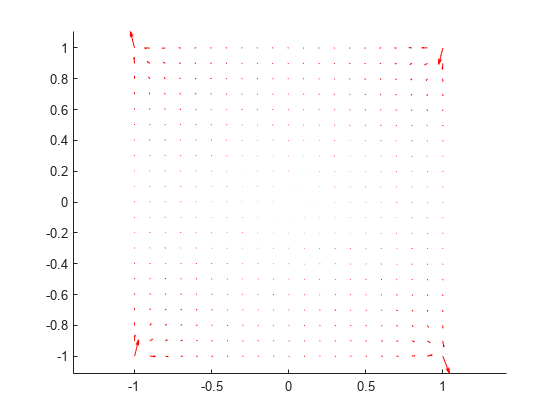

R = solve(emagmodel);
pdeplot(emagmodel,"FlowData",[R.MagneticFluxDensity.Bx ...
                              R.MagneticFluxDensity.By])
axis equal

Interpolate the resulting electric flux density to a grid covering the central portion of the geometry, for `x` and `y` from `-0.5` to `0.5`.

v = linspace(-0.5,0.5,51);
[X,Y] = meshgrid(v);
Bintrp = interpolateMagneticFlux(R,X,Y)

Bintrp =   FEStruct with properties:

    Bx: [2601x1 double]
    By: [2601x1 double]


Reshape `Bintrp.Bx` and `Bintrp.By` and plot the resulting magnetic flux density.

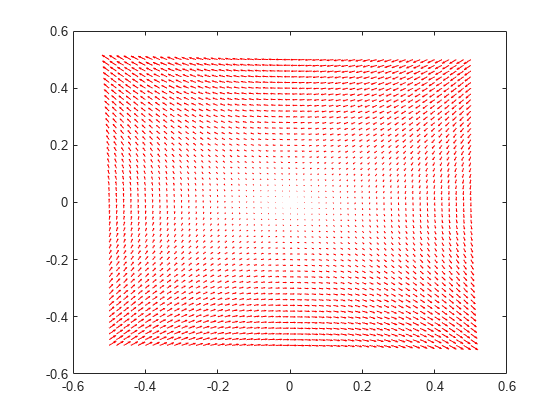

BintrpX = reshape(Bintrp.Bx,size(X));
BintrpY = reshape(Bintrp.By,size(Y));
figure
quiver(X,Y,BintrpX,BintrpY,"Color","red")

Alternatively, you can specify the grid by using a matrix of query points.

querypoints = [X(:),Y(:)]';
Bintrp = interpolateMagneticFlux(R,querypoints);

*Copyright 2020 The MathWorks, Inc.*